# ヴィオラの音を使ったチェロ音の合成

背景

- ヴァイオリンとヴィオラは構え方が同じ：両方演奏できる人は多い（実際音楽大学にてヴァイオリンを先行する人の多くは副科でヴィオラを選択する）

- しかし、同じヴァイオリン属であってもチェロは構え方が異なり、ヴァイオリンを演奏できる人でも学習コストが高い

- 古くからある演奏形態として「弦楽四重奏」がある（2ヴァイオリン+ヴィオラ+チェロ）

- 現代においても演奏機会・収録機会が多い。また、ポピュラー音楽にも多く用いられる。

- ヴァイオリンを弾ける人は、チェロさえ弾ければ多重録音によって弦楽四重奏を一人で収録できる

- チェロとオクターブの関係にあり、ボディの長さもおよそ1/2倍の関係にあるヴィオラの収録音を使ってチェロの音色を合成することで自然な合成が期待できる

filepath = "./unamed_/";
filename_va = "va/va_e3.wav";
filename_vc = "vc/vc_e2.wav";

compare their spectrol

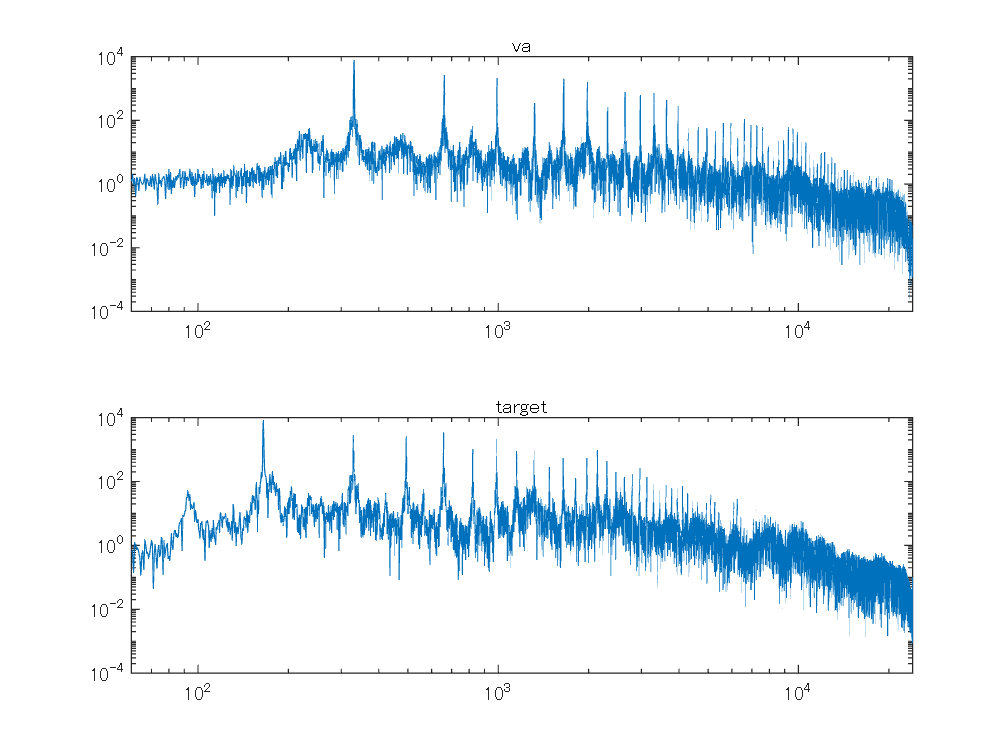

s_va = audioread(filepath + filename_va);
[s_vc,fs] = audioread(filepath + filename_vc);

% 信号長をそろえる
if length(s_va) < length(s_vc)
    s_vc = s_vc(1:length(s_va));
else
    s_va = s_va(1:length(s_vc));
end

N = length(s_va);
fnq = ceil(fs/2);
hamWin = hamming(N);
spectol_va = abs(fft(s_va .* hamWin));
spectol_vc = abs(fft(s_vc .* hamWin));

axis_freq = fs * (1:N) / N;
figure
tiledlayout(2,1)
nexttile
loglog((axis_freq), spectol_va);
xlim([60,fnq]); title("va")
nexttile
loglog((axis_freq), spectol_vc);
xlim([60,fnq]); title("target")

Time Scale Modificationの概念図 [1]

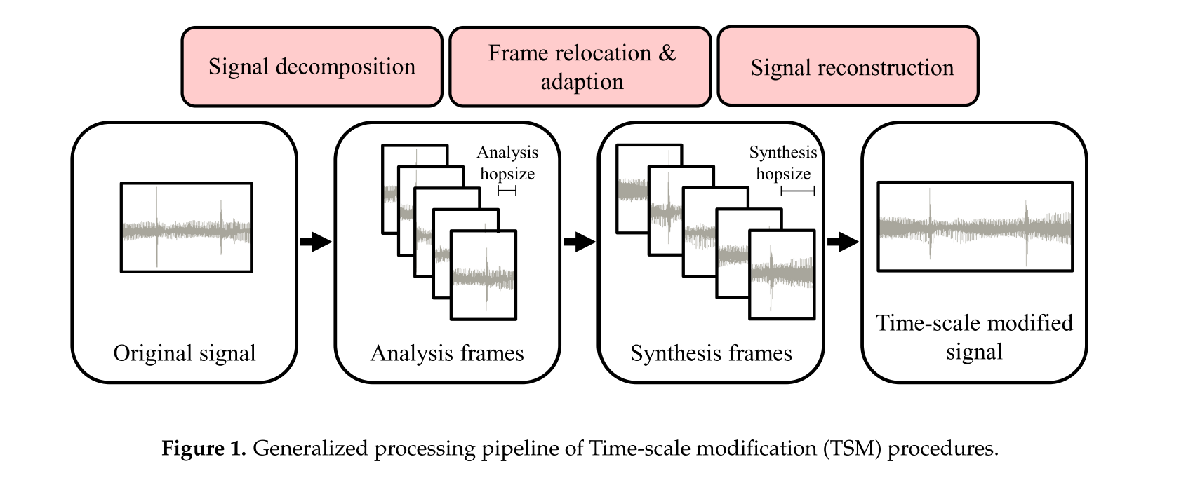

Wave form Similarity Overlap Add  (WSOLA) の概念図 [1]

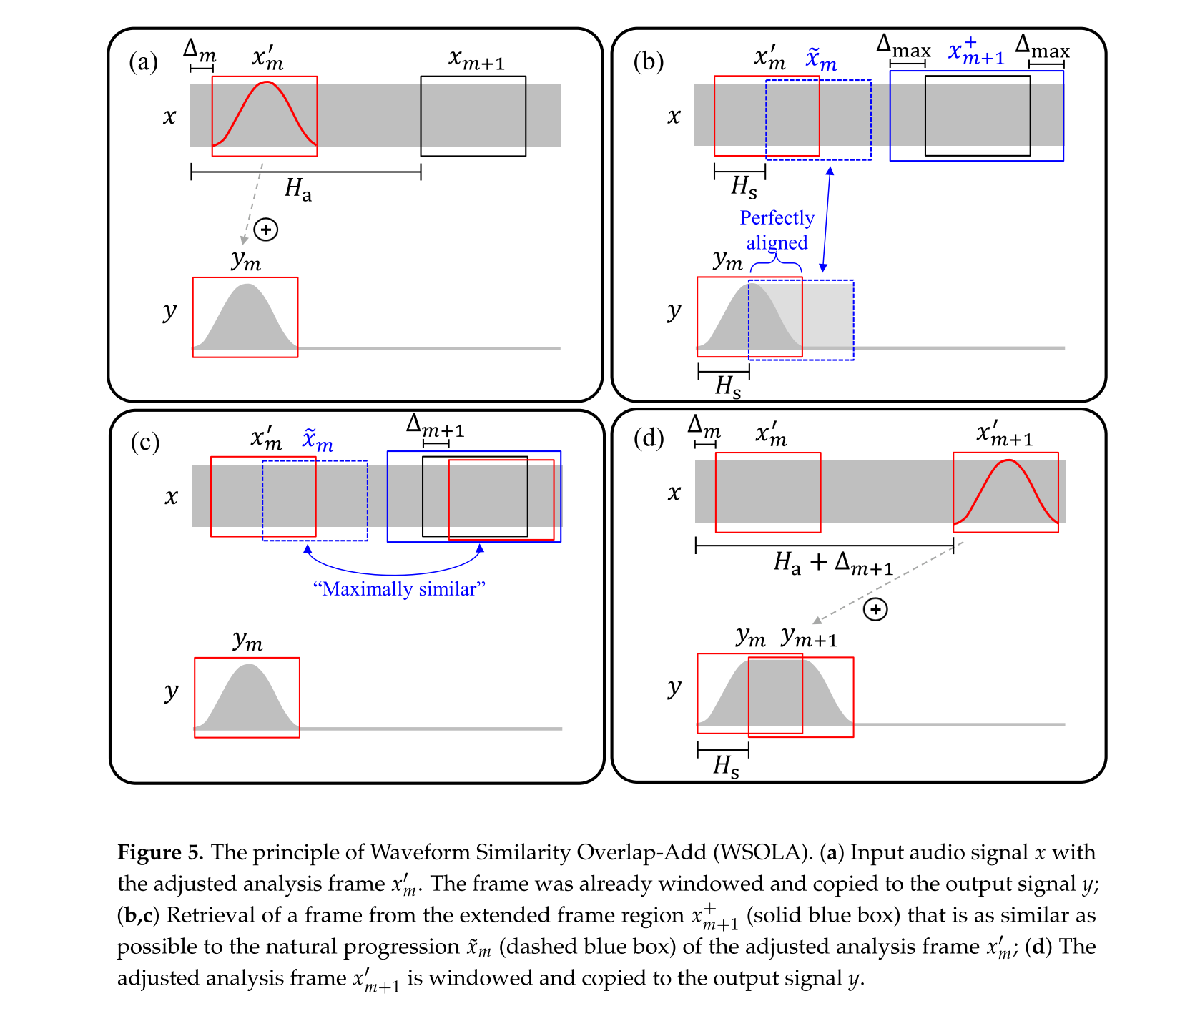

[1] Jonathan Driedger and Meinard Müller, A Review of Time-Scale Modification of Music Signals, Applied Sciences, 2016

ピッチシフトの結果とターゲット（VC）のスペクトルを比較（横軸は線形）

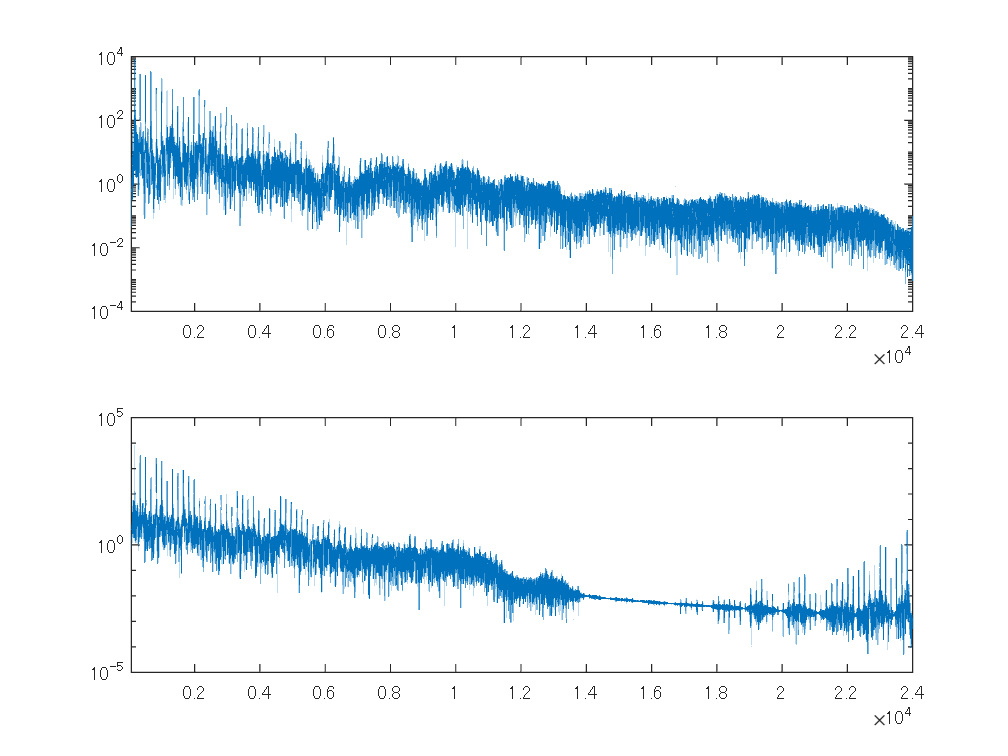

insertionMethod = ["linear","pchip","spline"];
%tx = (1:length(s_va_wsola))/(2*length(s_va_wsola))';
figure
tiledlayout(2,1)
nexttile
%semilogx((axis_freq), spectol_vc);
semilogy((axis_freq), spectol_vc);
xlim([60,fnq])
s_va_wsola = wsolaTSM(s_va, 0.5);
s_va_wsola_resample = resample(s_va_wsola, 2, 1);
spectol_va_wsola = abs(fft(s_va_wsola_resample .* hamWin));

nexttile
%semilogx((axis_freq), spectol_va_wsola);
semilogy((axis_freq), spectol_va_wsola);
xlim([60,fnq])

resample した信号について、ナイキスト周波数の半分以下にのみ成分を持っていてほしいが、そうなってない

->ハイパスフィルタで取り出して聞いてみる

artifact = highpass(s_va_wsola_resample, fs/4, fs);
%artifact = artifact / max(abs(artifact));
sound(artifact, fs); pause(3)
% 私の（劣化した）聴覚細胞では聞こえない
% 念のためローパスフィルタをかけておく
s_va_wr_lowpass = lowpass(s_va_wsola_resample, fs/4, fs);
sound(s_va_wsola_resample, fs); pause(3)
sound(s_va_wr_lowpass, fs)

- リサンプルをほどこした信号

- それにハイカットを施したもの

- ターゲット（VC）

を両対数プロット

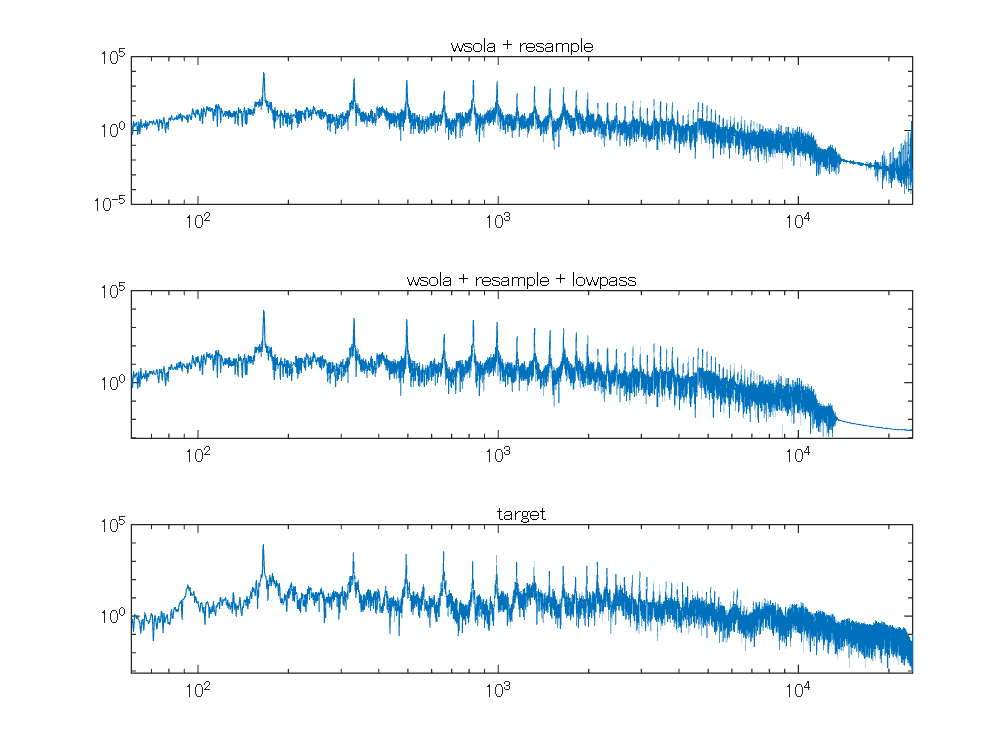

spectol_va_wr = abs(fft(s_va_wsola_resample .* hamWin));
spectol_va_wrl = abs(fft(s_va_wr_lowpass .* hamWin));
figure
tiledlayout(3,1)
nexttile
loglog((axis_freq), spectol_va_wr);
xlim([60,fnq]); title("wsola + resample")
nexttile
loglog((axis_freq), spectol_va_wrl);
xlim([60,fnq]); title("wsola + resample + lowpass")
nexttile
loglog((axis_freq), spectol_vc);
xlim([60,fnq]); title("target")

## 2.2 TSM後の処理

TSM -> resample ではナイキスト周波数の半分以上の成分を合成できない

TSM前の信号の高周波成分を貼り付ける

s_va_hp = highpass(s_va,fnq/2,fs);

さらに人工的に倍音を生成して付け加える

倍音の生成はハーモニックジェネレータ（以降HG、音声の分野ではexciterとも）を使用

HGは非対称三次ソフトクリッパーを実装（参考

[https://wiki.analog.com/resources/tools-software/sigmastudio/toolbox/nonlinearprocessors/asymmetricsoftclipper](https://wiki.analog.com/resources/tools-software/sigmastudio/toolbox/nonlinearprocessors/asymmetricsoftclipper)

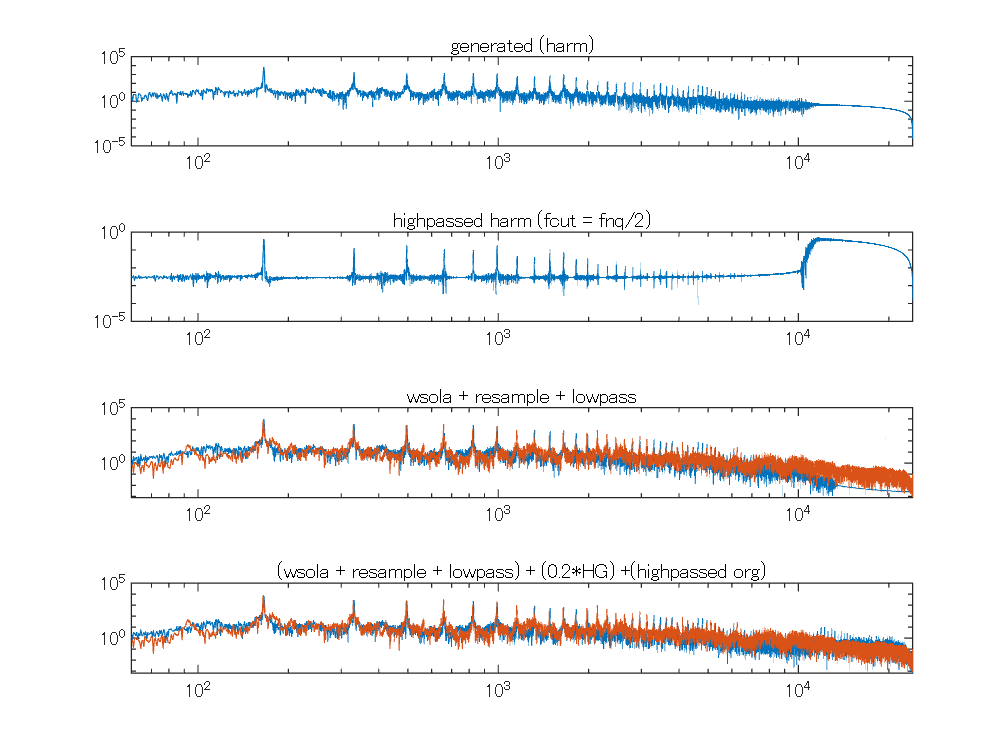

harm = asymmetricCubicSoftClipper(s_va_wr_lowpass);
sound(harm, fs)
pause(3)
harm_hp = highpass(harm, fnq/2, fs);
sound(harm_hp, fs)

figure
tiledlayout(4,1)
nexttile
loglog(axis_freq, abs(fft(harm.* hamWin)))
xlim([60,fnq]); title("generated (harm)")
nexttile
loglog(axis_freq, abs(fft(harm_hp.* hamWin)))
xlim([60,fnq]); title("highpassed harm (fcut = fnq/2)")
nexttile
loglog((axis_freq), spectol_va_wrl);
hold on
loglog((axis_freq), spectol_vc);
xlim([60,fnq]); title("wsola + resample + lowpass")
nexttile
loglog((axis_freq), abs(fft((s_va_wr_lowpass + harm * 0.2 + s_va_hp).* hamWin)));
hold on
loglog((axis_freq), spectol_vc);
xlim([60,fnq]); title("(wsola + resample + lowpass) + (0.2*HG) +(highpassed org)")